**Part I: Seasonal Trend Decomposition – Additive Modeling**

clear
load hw2_1.mat;
date = datestr(data.time,'mm/dd/yyyy'); 
hour = datestr(data.time,'HH'); 
data = addvars(data, date, hour,'Before','time','NewVariableNames',{'date', 
'hour'}); 

hourly_data = grpstats(data,{'date','hour'},{'mean'},'DataVars',{'pm2d5'});
time_str = strcat(hourly_data.date,':',hourly_data.hour);
time_dateHr = datetime(time_str,'InputFormat','MM/dd/yyyy:HH');

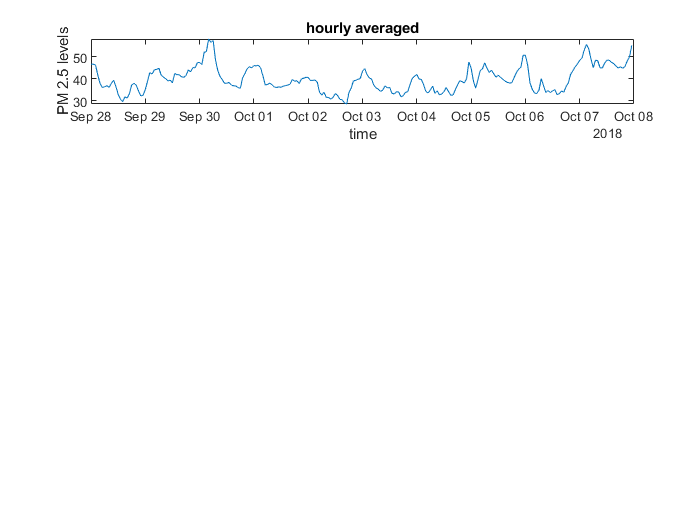

figure
subplot (4,1,1)
plot(time_dateHr ,hourly_data.mean_pm2d5);
title('hourly averaged'), ylabel('PM 2.5 levels'), xlabel('time')

a) Please see the hourly averaged plot above.

b) T = 24 hrs. I chose this specific periodicity (T) because I wanted to focus on the seasonal changes happening each day. I also wanted to see the overall daily trend across the 10 days period which represents the changes due to environmental factors.

If T is halved, the seasonal changes would be representation of half a day and that would make the overall trend more granular. If T is doubled, 2 day period would be the representation of seasonal changes and the overall trend would be less granular.

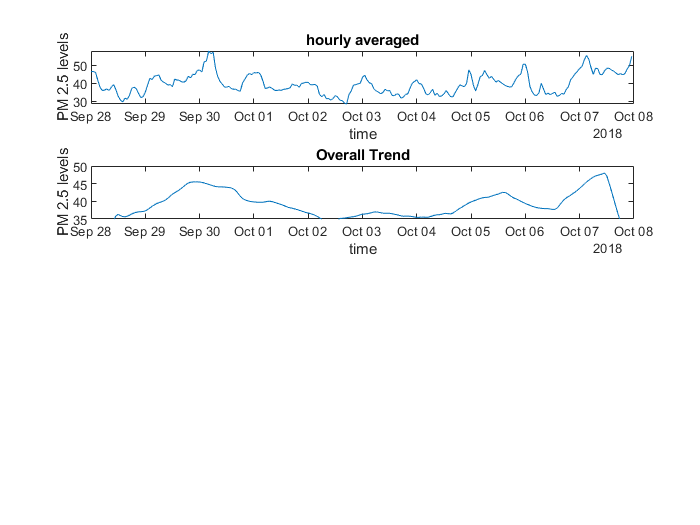


sW25 = [1/48;repmat(1/24,23,1);1/48];  
trend = conv(hourly_data.mean_pm2d5,sW25,'same'); s = 24;
subplot(4,1,2)
plot(time_dateHr ,trend)
ylim([35,50])
title('Overall Trend'), ylabel('PM 2.5 levels'), xlabel('time')

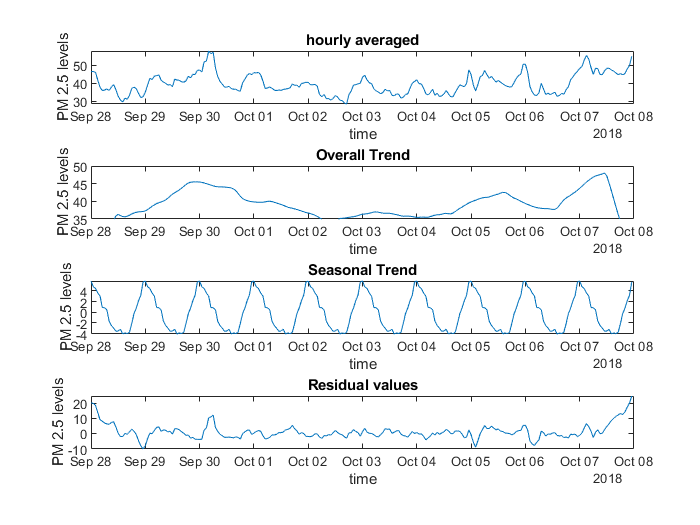

T = length(hourly_data.mean_pm2d5);
sidx = cell(s,1);
for i = 1:s
    sidx{i,1} = i:s:T;
end
detrend_data = hourly_data.mean_pm2d5-trend; % detrend data
seasonal = cellfun(@(x) mean(detrend_data(x)),sidx);
nc = floor(T/s);
rm = mod(T,s);
seasonal = [repmat(seasonal,nc,1);seasonal(1:rm)];
sBar = mean(seasonal);
seasonal = seasonal-sBar; % Obtain seasonal signal
residual = hourly_data.mean_pm2d5-trend-seasonal; % Residual
subplot(4,1,3)
plot(time_dateHr, seasonal)
title('Seasonal Trend'), ylabel('PM 2.5 levels'), xlabel('time')
subplot(4,1,4)
plot(time_dateHr, residual)
title('Residual values'), ylabel('PM 2.5 levels'), xlabel('time')

c) In the seasonal trend, we see a consistent daily change pattern of PM 2.5 levels. After the overall trend is removed and ignoring any stochastic noises, what we have is a very consistent daily seasonal patterns of PM 2.5 levels with the priodicity of 24 hours. If T is reduced to half or increased to 2T, it would change the periodicity of the data as per the given T but the overall seasonal trends will remain the same.

d) Since the residual plot doesn't show any discernible pattern with an average value close to 0, I think most patterns in the PM 2.5 data have been extracted in the trend and seasonality.

e) We see from the overall trend that the PM 2.5 levels dropped from September 30th to October 3rd and went back up again. Since the seasonal daily trends stayed consistent in the 10-day period, there seems to be some environmental factor(s) affecting the overall trend. Additive decomposition can therefore be used to isolate factors affective overall trend and seasonal trends of PM 2.5 data pattens. It also seems to be effective in removing noises.

**Part II: Singular Value Decomposition**

                                                         % PART II
clear
load hw2_1.mat;
%Averaging values for each minute
tt = table2timetable(data);
minute_data = retime(tt,'minutely','mean');


%Constructing Data Matrix
data_matrix= reshape(minute_data.pm2d5,[1440,10])';
for ii= 1:10
    data_matrix(ii,:)= normalize(data_matrix(ii,:)','range'); %Normalized Final Data Matrix
end
data_matrix = fillmissing(data_matrix,'linear');

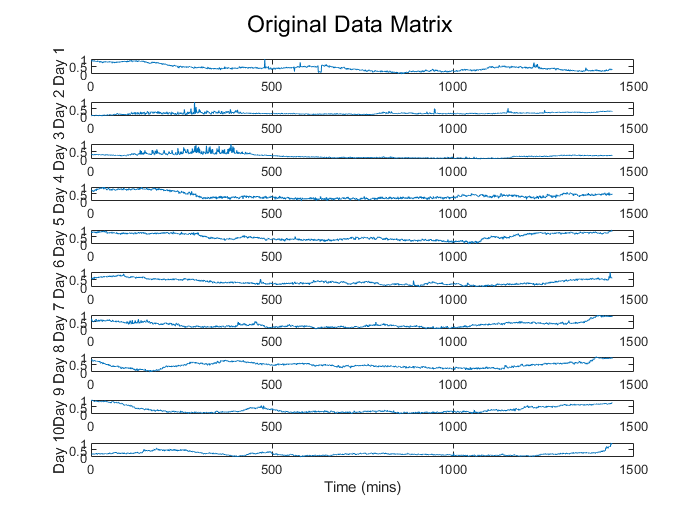

mins_xlabel=[1:1440];
figure
for ii=1:10
    subplot(10,1,ii)
    plot(mins_xlabel, data_matrix(ii,:))
    ylabel_text= sprintf("Day %.0f", ii);
    ylabel(ylabel_text);
end
sgtitle('Original Data Matrix')
xlabel('Time (mins)')

a) Figure above shows the full data matrix for 10 days' PM 2.5 levels.

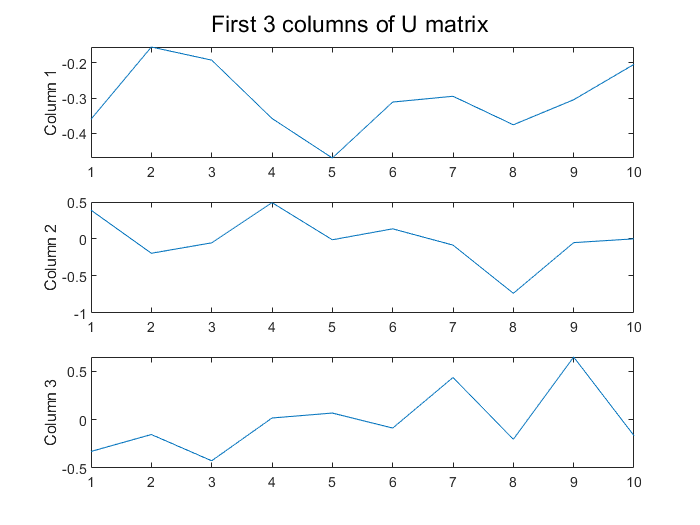


%SVD
[U,S,V] = svd(data_matrix);

%Plotting U 1st 3 columns
figure
for ii=1:3
    subplot(3,1,ii)
    plot(U(:,ii))
    ylabel_text= sprintf("Column %.0f", ii);
    ylabel(ylabel_text);
end
sgtitle ('First 3 columns of U matrix')

b) See above for the 1st three columns of the U matrix.

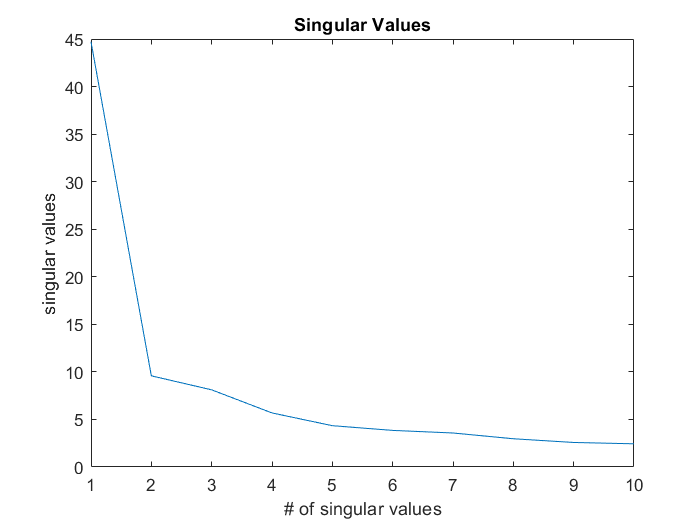

figure
plot(diag(S));
title ('Singular Values')
xlabel('# of singular values'), ylabel('singular values')

c) See above for all the singular values. These values represent the square root of eignevalues of the original data matrix. We can see that the first eignenvalue is substantially higher than the rest and decreases almost exponentially to later values.

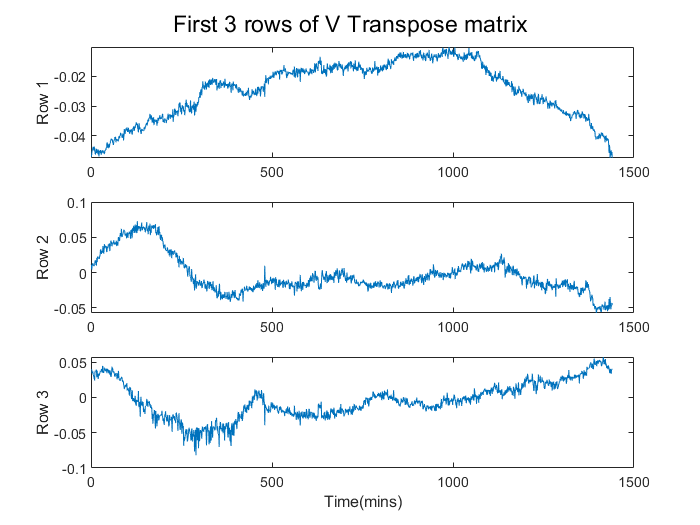

%Plotting V_transpose 1st 3 rows
V_T=V'; 
figure
for ii=1:3
    subplot(3,1,ii)
    plot(mins_xlabel, V_T(ii,:))
    ylabel_text= sprintf("Row %.0f", ii);
    ylabel(ylabel_text);
end
xlabel('Time(mins)')
sgtitle ('First 3 rows of V Transpose matrix')

d) The first 3 rows of V_Transpose matrix show 3 distinct patterns. This matrix (each row) represents the orthonormal eigenvectors of the original data matrix, that are also potential principal component analysis axes.

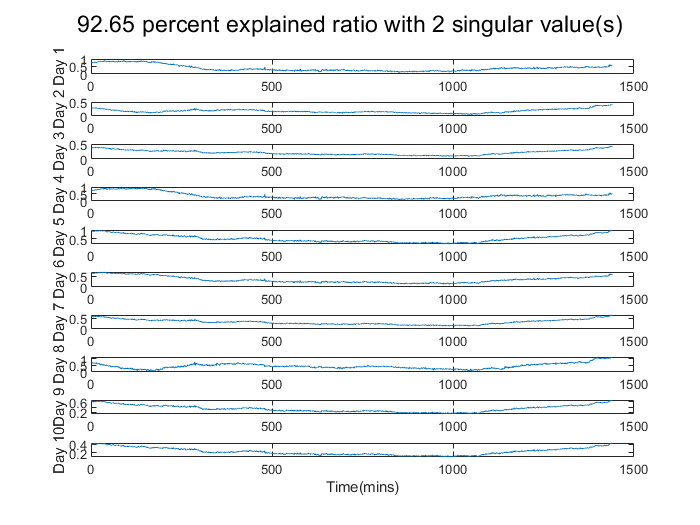

% Data matrix reconstruction with SVD and explained ratios
singular_vals = diag(S);
n=2; % Input number of singular values chosen
explained_ratio = sum(singular_vals(1:n).^2)/sum(singular_vals.^2);
Re_datamatrix = U(:,1:n)*S(1:n,1:n)*V_T(1:n,:);
%Plotting the Reconstructed Matrix
figure
for ii=1:10
    subplot(10,1,ii)
    plot(mins_xlabel, Re_datamatrix(ii,:))
    ylabel_text= sprintf("Day %.0f", ii);
    ylabel(ylabel_text);
end
header = sprintf("%.2f percent explained ratio with %.0f singular value(s)", explained_ratio*100,n);
sgtitle(header)
xlabel('Time(mins)')

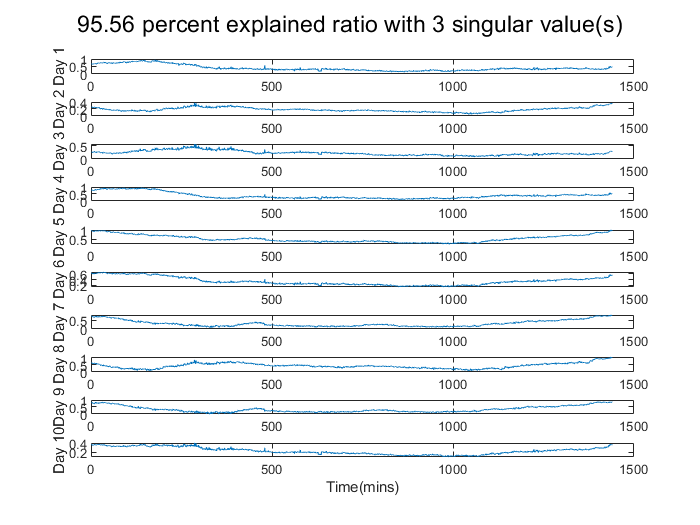


% Data matrix reconstruction with SVD and explained ratios
singular_vals = diag(S);
n=3; % Input number of singular values chosen
explained_ratio = sum(singular_vals(1:n).^2)/sum(singular_vals.^2);
Re_datamatrix = U(:,1:n)*S(1:n,1:n)*V_T(1:n,:);
%Plotting the Reconstructed Matrix
figure
for ii=1:10
    subplot(10,1,ii)
    plot(mins_xlabel, Re_datamatrix(ii,:))
    ylabel_text= sprintf("Day %.0f", ii);
    ylabel(ylabel_text);
end
header = sprintf("%.2f percent explained ratio with %.0f singular value(s)", explained_ratio*100,n);
sgtitle(header)
xlabel('Time(mins)')

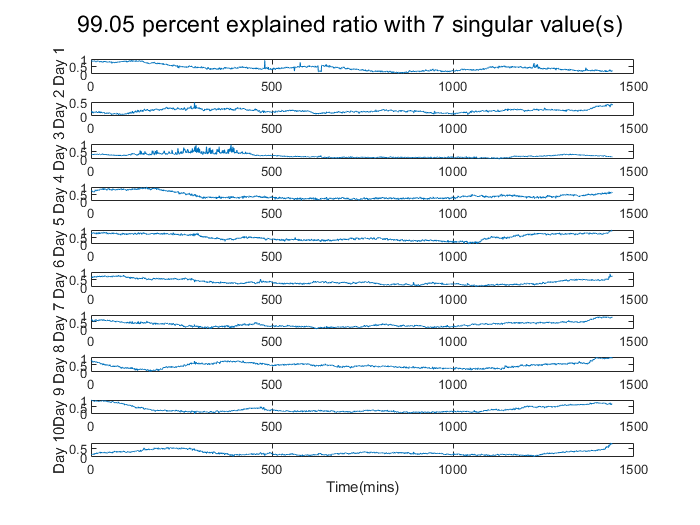

% Data matrix reconstruction with SVD and explained ratios
singular_vals = diag(S);
n=7; % Input number of singular values chosen
explained_ratio = sum(singular_vals(1:n).^2)/sum(singular_vals.^2);
Re_datamatrix = U(:,1:n)*S(1:n,1:n)*V_T(1:n,:);
%Plotting the Reconstructed Matrix
figure
for ii=1:10
    subplot(10,1,ii)
    plot(mins_xlabel, Re_datamatrix(ii,:))
    ylabel_text= sprintf("Day %.0f", ii);
    ylabel(ylabel_text);
end
header = sprintf("%.2f percent explained ratio with %.0f singular value(s)", explained_ratio*100,n);
sgtitle(header)
xlabel('Time(mins)')

e) i, ii, iii ----> 2, 3, and 7 singular values are required respectively. Please see above.

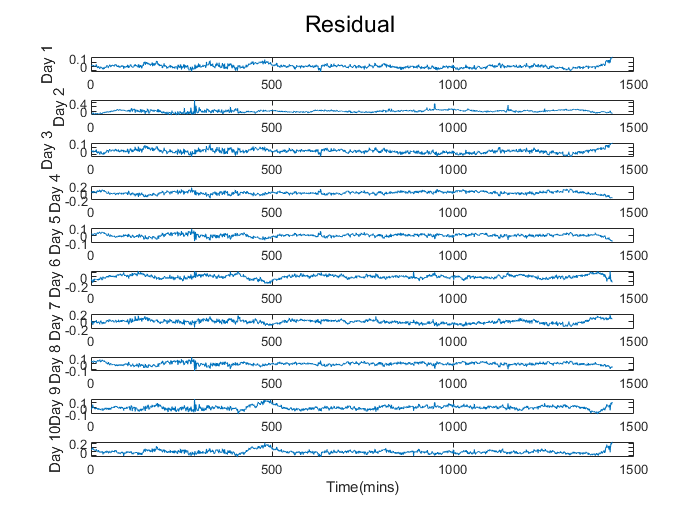

Residual = data_matrix - Re_datamatrix;

%Plotting the Residual Matrix
figure
for ii=1:10
    subplot(10,1,ii)
    plot(mins_xlabel, Residual(ii,:))
    ylabel_text= sprintf("Day %.0f", ii);
    ylabel(ylabel_text);
end
xlabel('Time(mins)')
sgtitle('Residual')                                       

e) iv) The residual plots each day seem to center around the approximate average value of 0. The residual values seem to fluctuate a lot more for the first 500 minutes of each day and the rest of the time they seem to be relatively constant around average.

**Part III : Data Statistical Analysis.**

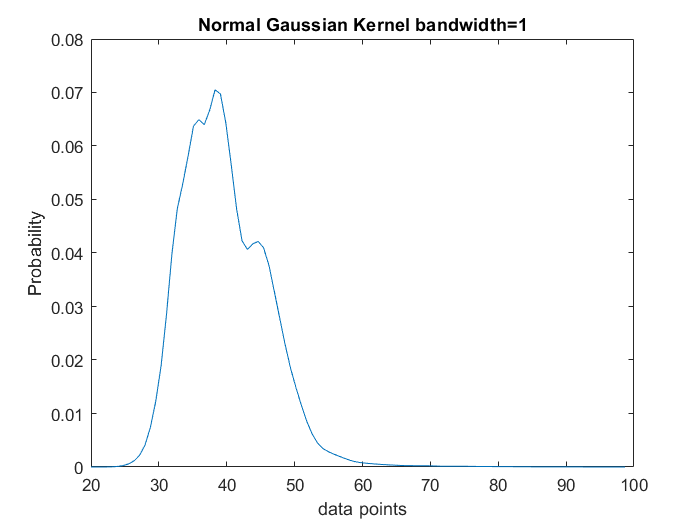

% PART III
clear
load hw2_1.mat;
[f,xi] = ksdensity(data.pm2d5,'Bandwidth',1);
figure
plot(xi, f)
title('Normal Gaussian Kernel bandwidth=1'), xlabel('data points'), ylabel('Probability');

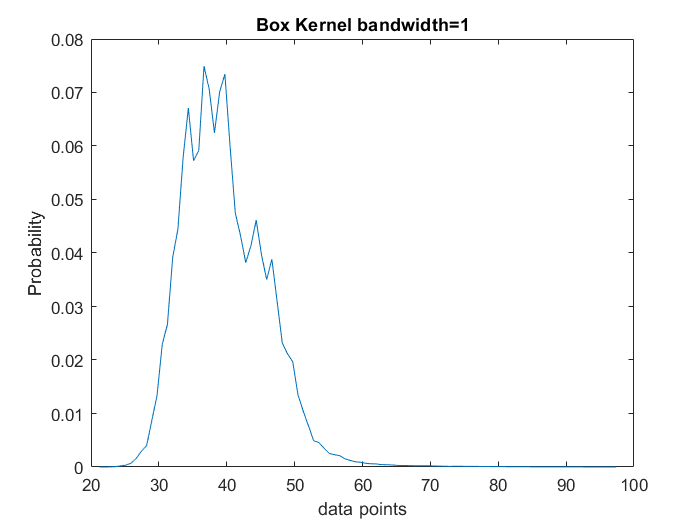

[f,xi] = ksdensity(data.pm2d5,'Bandwidth',1,'Kernel','box');
figure
plot(xi, f)
title('Box Kernel bandwidth=1'), xlabel('data points'), ylabel('Probability');

a) i, ii )   See the plots above.

iii) In both the Gaussian and Box Kernel plots, we see  the x-ranges, y-ranges, and overall trend to be the same.  The Box plot pdf curve however, seems to be less smooth with the distinct edges of box kernels seen as local spikes in probability function. I think the Gaussian Kernel pdf better represents the data because it is smoother and more representative of the continuous distribution of data that we have with PM 2.5 time series.

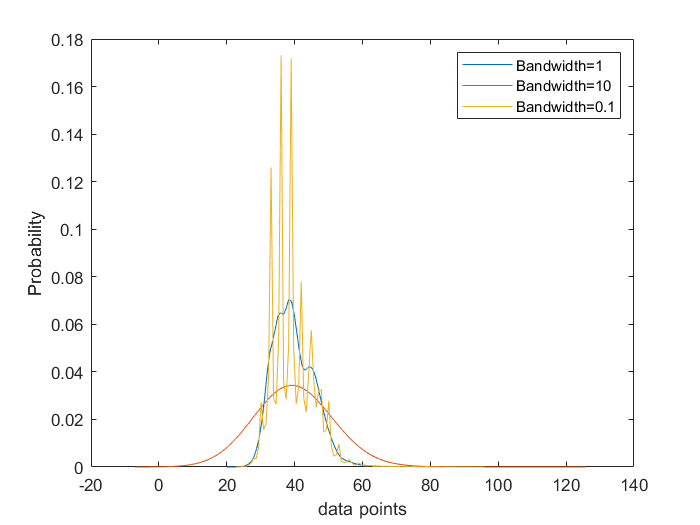

[f,xi] = ksdensity(data.pm2d5,'Bandwidth',1);
figure
plot(xi, f)
hold on
[f,xi] = ksdensity(data.pm2d5,'Bandwidth',10);
plot(xi, f)
[f,xi] = ksdensity(data.pm2d5,'Bandwidth',0.1);
plot(xi, f)

legend('Bandwidth=1','Bandwidth=10','Bandwidth=0.1'),xlabel('data points'), ylabel('Probability');
hold off

b) We see from the plots above that as we decrease the bandwidth values of the Gaussian Kernel, the distribution becomes too localized (Bandwidth=0.1) to the individual data points and hence- too spiky in appearance. Similarly, on the other end of the spectrum- if we increase the bandwidths too much (Bandwidth=10), the distribution gets over-averaged and loses almost all local information. Hence, Bandwidth=1 seems to be the most appropriate with a good balance of not being too localized, but not over-averaged out either.

% Descriptive Statistics
clear
load hw2_1.mat;
mean_data = mean(data.pm2d5)

mean_data = 39.7287

median_data = median(data.pm2d5)

median_data = 39

stddev = std(data.pm2d5)

stddev = 6.1111

skew = skewness(data.pm2d5)

skew = 0.9813

kur = kurtosis(data.pm2d5)

kur = 5.9600

c) With a skewness value of 0.9813 , and the mean and median values being very close, the distribution of PM 2.5 data seems to be just moderately skewed. The kurtosis of 5.96 > 3 (Gaussian) suggests that the distribution has stronger peaks and heavier tails (outliers) than the standard Gaussian distribution.